# Feature Engineering with Storm Events

## Introduction

In this reading you will import storm event data, extract the text for event descriptions along with the corresponding damage cost values, pre-process the data, find and extract features in the text to use for predicting damage, evaluate the features visually as well as ANOVA testing, and subsequently refine them further. 

Of the many factors that affect how much damage a hail storm causes, hail size is probably the best predictor. However, the storm event data doesn’t include hail size as a variable. Rather, there are text descriptions of the storm events containing qualitative descriptions of hail size. Here you can see several examples that use common items for size reference instead of giving numerical measurements. 

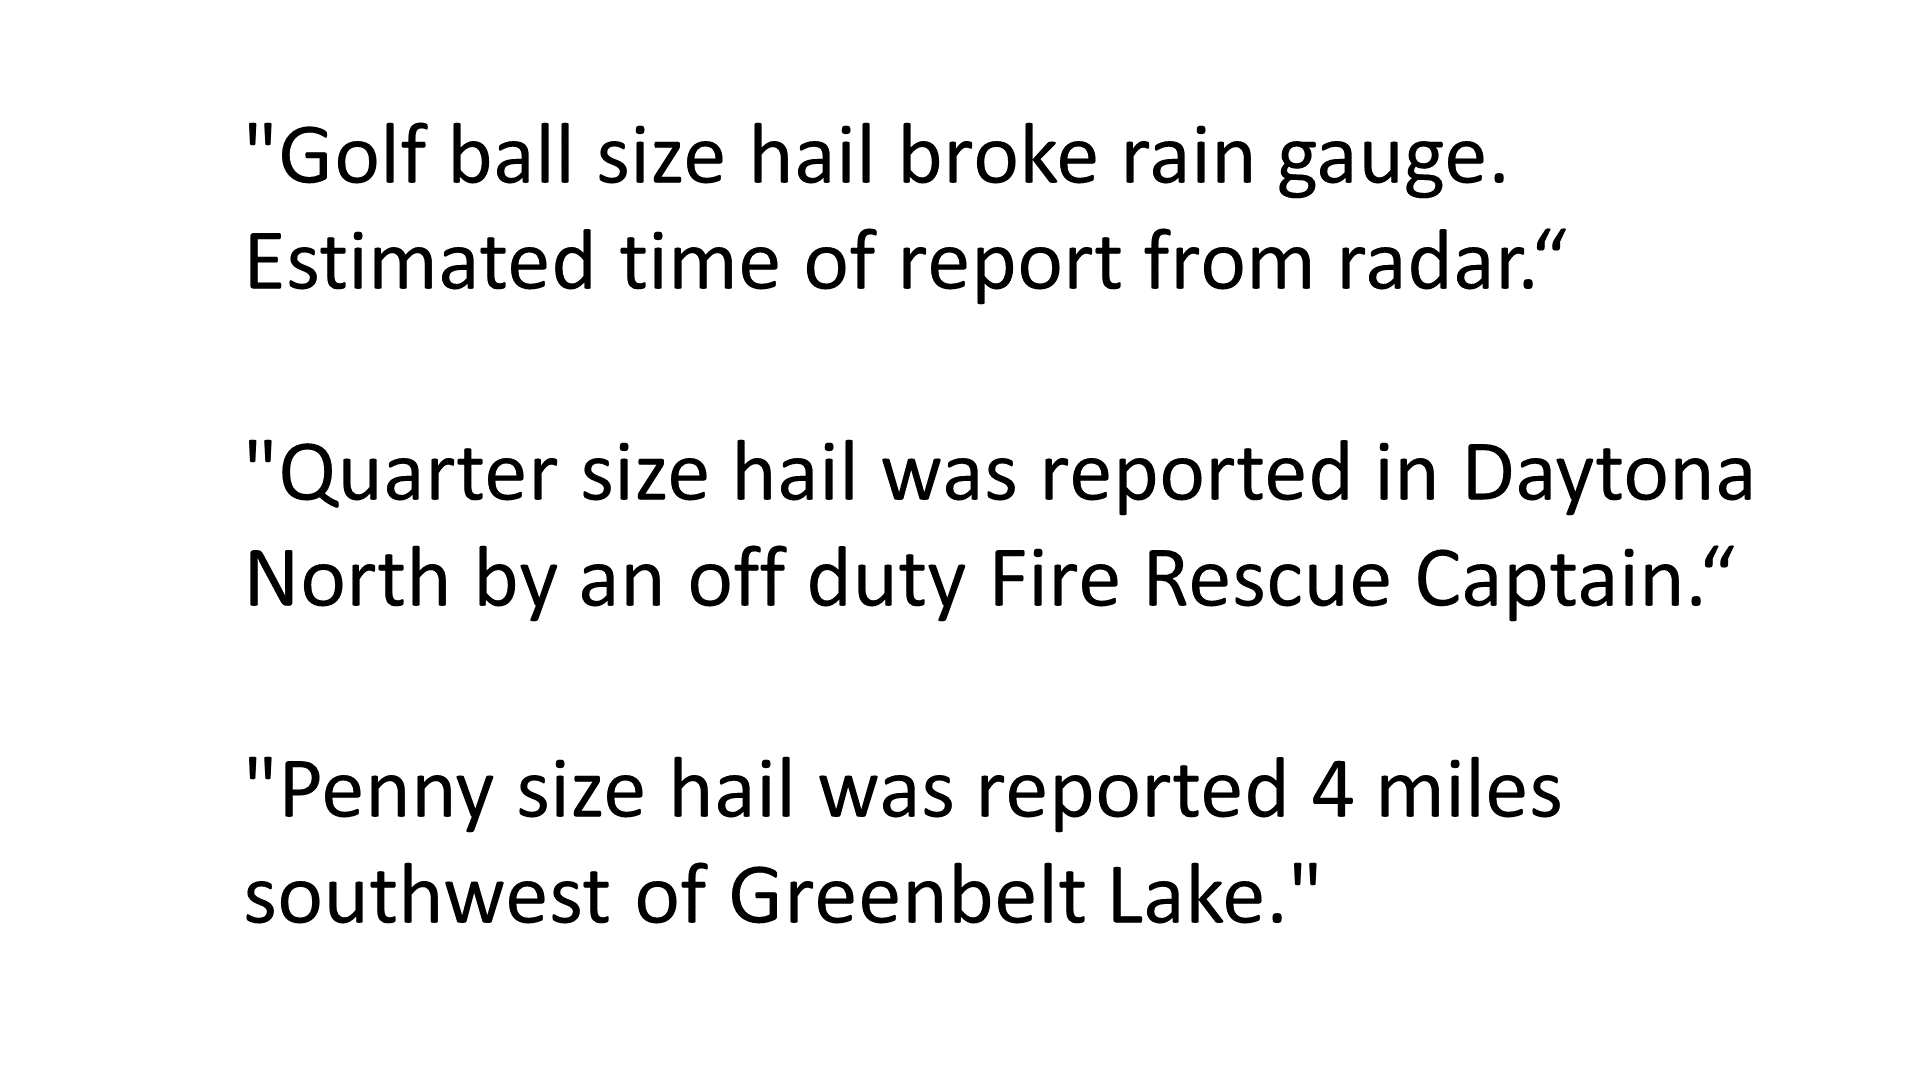

Item names with known sizes in the descriptions of hail storms are features that you could use to predict damage.

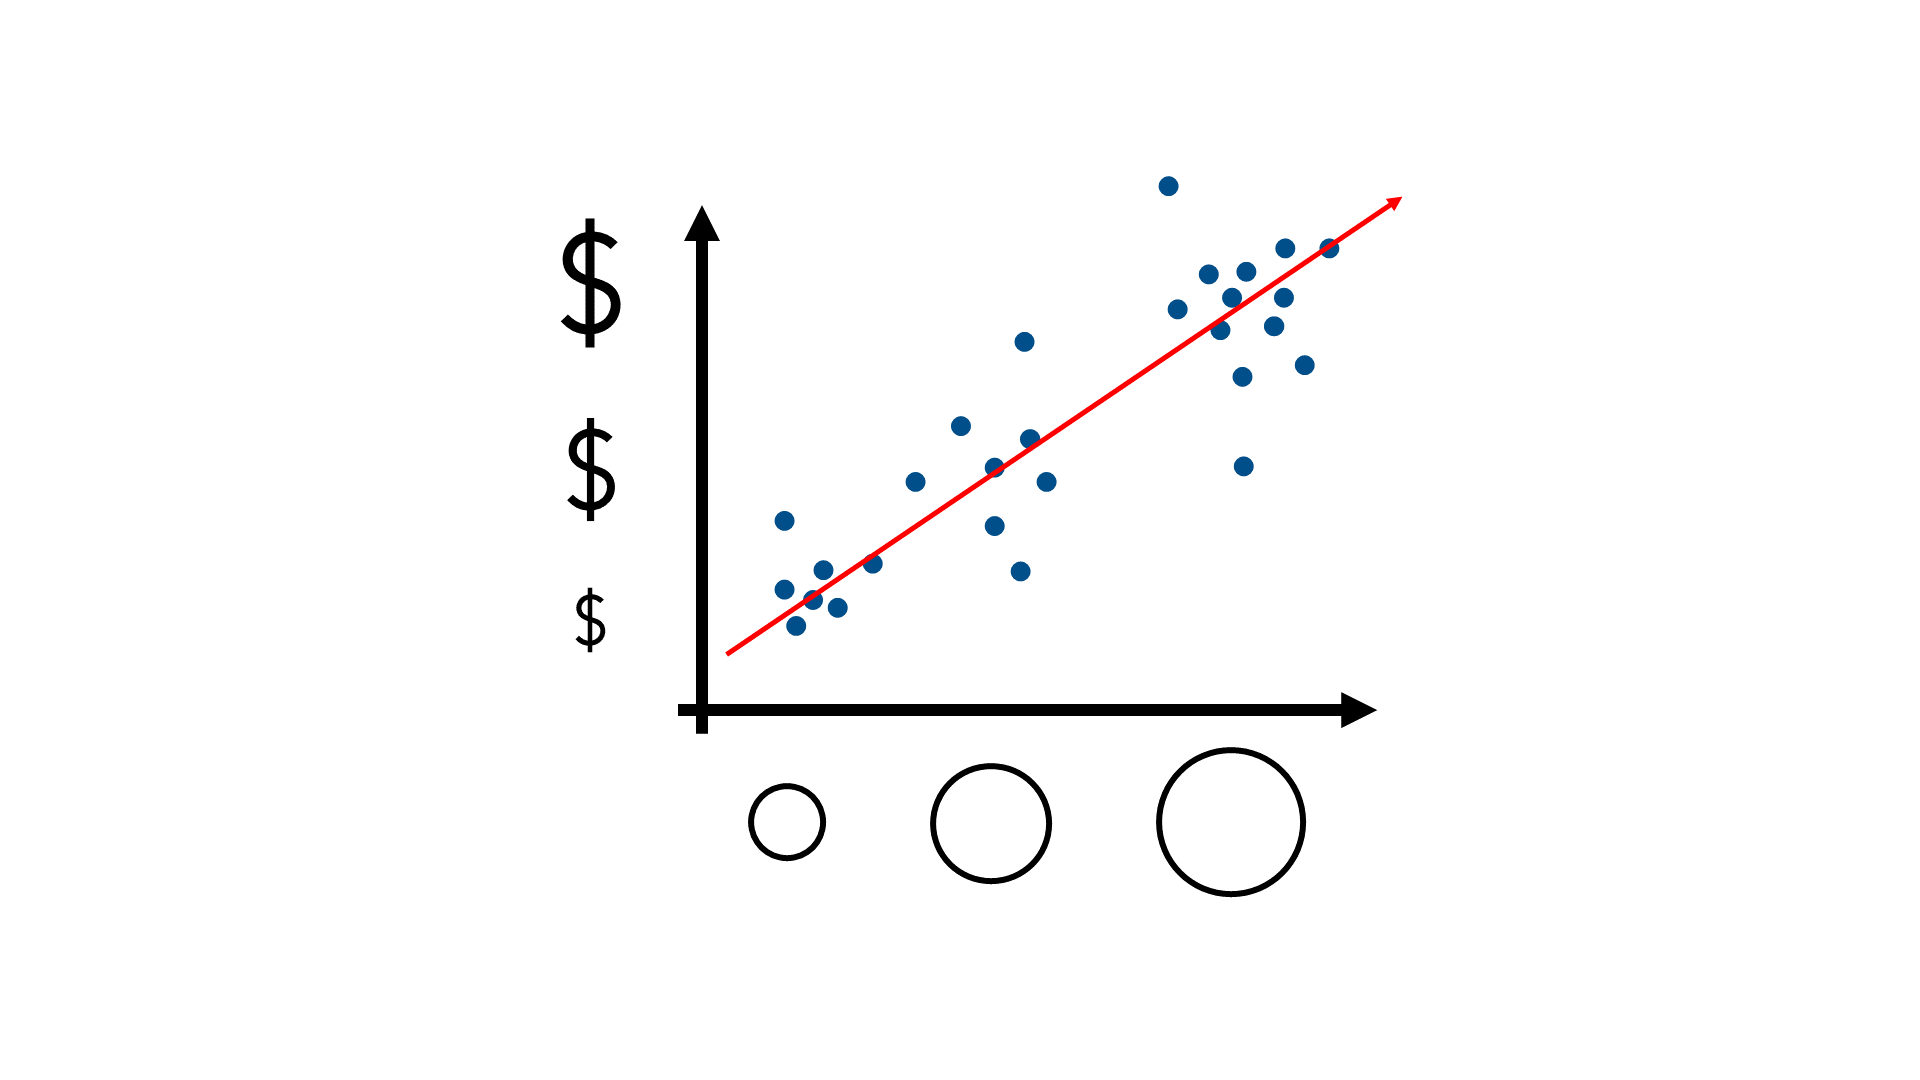

Before you can start processing the text to identify useful features, you'll need to import it.

**Note:** as you proceed through this reading, it will be best to run each section individually in sequence. 

## Import data

You will need the storm events data for Exploratory Data Analysis (Course 1). The data could be imported using the Import Tool with some processing, but this time you can just use the code below. If you completed Course 1, you should be able to use your own import function as well. If you haven't already, make sure the folder containing the Storm Events files is on the search path.

events = importStormData("StormEvents_2016.csv")

The first time you go through this reading, you should just use *StormEvents_2016.csv*.  However, if later you want to import all of the storm event files at once, you can use a datastore. In this case you'll need to do a few things: 

- Locate the file path on your system with the storm events data for Exploratory Data Analysis (Course 1)`. `For example, "C:\Courses\Exploratory Data Analysis\StormEvents".

- Remove *StormEvents_2017_finalProject.csv* from the directory since you won't want to duplicate data in *StormEvents_2017.csv*

- Uncomment the code below and modify the file path "S:\Coursera Development\Exploratory Data Analysis\Course Files\StormEvents" to match the one you found in Step 1. 

% ds = fileDatastore("C:\Coursera Development\Exploratory Data Analysis\ ...
%   Course Files\StormEvents", "ReadFcn", @importStormData, "UniformRead",true);
% events = readall(ds);

Now combine property and crop cost into a single total. 

% Replace all NaN values with 0
events.Property_Cost = fillmissing(events.Property_Cost,"constant",0);
events.Crop_Cost = fillmissing(events.Crop_Cost,"constant",0);

events.Cost = events.Property_Cost + events.Crop_Cost; 

Now extract hail events with non-missing entries using logical indexing and the & (AND) operator. Note that an empty string in the Event Narrative does not get flagged by `ismissing`, so you could pass `""` as an indicator, or use a function like `strlength` to ignore empty strings.

% Filter out the hail events
rows2keep = events.Event_Type=="Hail" & ~ismissing(events.Cost) & ...
    strlength(events.Event_Narrative) > 0; 
cols2keep = ["Event_Narrative","Cost"];
events = events(rows2keep,cols2keep);


% Check how hyphens are used in event narratives
hasHyphen = contains(events.Event_Narrative,"-");
disp(events.Event_Narrative(hasHyphen))

## Perform Pre-processing

If you look at the descriptions above, you can see that some of them contain hyphenated words. Since you need to evaluate each word separately, start by replacing all hyphens with a space.

% Replace dashes with spaces so things like "quarter-sized" get 
% counted as separate words
events.Event_Narrative = replace(events.Event_Narrative,"-"," ");

Now use the `tokenizedDocument` function to break each string into components. 

documents = tokenizedDocument(events.Event_Narrative);


Visualizing the result with a word-cloud reveals lots of punctuation and stop words, which make it more difficult to identify useful features. Remove them using the `erasePunctuation` and `removeStopWords` functions.

% Erase punctuation.
documents = erasePunctuation(documents);
% Remove a list of stop words.
documents = removeStopWords(documents);

## Find Features in Text Descriptions 

Now take another look at the word-cloud above. You’ll notice “size” and “sized” are both common words. These are good places to start looking for features since reference object words will often appear next to them. Use the `normalizeWords` function to reduce the words to their root form in lower case for easier searching. 

documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','lemma');

% Update word-cloud 
wordcloud(documents); 

Next, you'll need to find word sequences containing "size". 

### Extract Multi-Word Sequences 

Similar to the bag-of-words model you’ve seen previously, you can find two-word sequences or bigrams using the `bagOfNgrams` function. 

bag2 = bagOfNgrams(documents,"NgramLengths",2) 
bag2.Ngrams

You can then use this to extract all of the words that come immediately before all variations of “size”: 

wordsBeforeSize = bag2.Ngrams(bag2.Ngrams(:,2) == "size",:) 

Notice the words for US coins like “quarter”, “dime”, “nickel”, and “penny”, sports items like “baseball” and “softball”, and food items like “pea” and “grapefruit”. You can also see words like “ball” and “dollar” and "pong". What words come before them? To see this, extract the three-word sequences or trigrams and look for the words preceding “ball size”, “dollar size”, and "pong size". 

bag3 = bagOfNgrams(documents,"NgramLengths",3) 
wordsBeforeBallSize = bag3.Ngrams(bag3.Ngrams(:,2) == "ball" & ...
    bag3.Ngrams(:,3) == "size",:) 
wordsBeforeDollarSize = bag3.Ngrams(bag3.Ngrams(:,2) == "dollar" & ...
    bag3.Ngrams(:,3) == "size",:) 
wordsBeforePongSize = bag3.Ngrams(bag3.Ngrams(:,2) == "pong" & ...
    bag3.Ngrams(:,3) == "size",:)

There is “golf ball size", “tennis ball size", "billiard ball size", "half dollar size", and "ping pong size". You can probably safely assume that the word preceding "pong ball size" was "ping", but you can double check this as well.

### Perform Custom Normalization 

One thing you may have noticed above, is that both "nickle" and "nickel" showed up as alternative spellings for the same object.  You can perform a custom normalization to deal with this situation by using the `replaceWords` function. 

documents = replaceWords(documents,["nickle" ; "nickles"],"nickel");

Words like "golfball," "tennisball", "halfdollar", and "pingpongball" are not single words, but since you are more interested in finding the Ngrams than grammatical correctness, it may make it easier to substitute in the technically incorrect version and search for single "words": 

% You can replace each rows of an input string array using replaceNgrams.
% In order to replace both "golf ball" and "golfballs" by "golfball", Use a
% 2x2 string array with an empty string in the 2nd row and column. 
documents = replaceNgrams(documents,["golf" "ball" ; "golfballs" ""],"golfball" );
documents = replaceNgrams(documents,["tennis" "ball" ; "tennisballs" ""],"tennisball" ); 
documents = replaceNgrams(documents,["half" "dollar" ; "halfdollars" ""], "halfdollar" );
documents = replaceNgrams(documents,["ping" "pong" "ball" ; "ping" "pong" "" ; ...
    "pingpong" "ball" "" ; "pingpong" "" ""], "pingpongball" );

## Find and Rank Search Terms 

So far you've found and normalized a number of search terms corresponding to items in hail descriptions: 

- US coins “quarter”, “dime”, “nickel”, “penny”, and "halfdollar" 

- Sports items like “baseball”, “softball”, "golfball", "tennisball", "pingpongball", "billiard" 

- Food items like “pea” and “grapefruit”

To order these items by size, you can find the object-to-size conversions used by the United States National Weather Service for each by searching online: 

- [https://www.weather.gov/media/pbz/skywarn/Hail_Chart.pdf](https://www.weather.gov/media/pbz/skywarn/Hail_Chart.pdf)

- [https://www.nssl.noaa.gov/education/svrwx101/hail/](https://www.nssl.noaa.gov/education/svrwx101/hail/)

- [https://www.spc.noaa.gov/misc/tables/hailsize.htm](https://www.spc.noaa.gov/misc/tables/hailsize.htm)

Define a set of search words arranged by size

searchWords = ["pea","dime","penny","nickel","quarter","halfdollar","pingpongball",...
    "golfball","billiard","tennisball","baseball" ,"softball", "grapefruit"];

Now create a bag-of-words model to search for these terms.

bag = bagOfWords(documents);

Notice that you need to look for single "words" with a bag of words model since you normalized all multiple-word item descriptions to be single search terms. You could alternatively use a more complicated strategy by searching the bag-of-Ngrams models in addition to the bag-of-words model. 

To find the indexes of these words in the `Vocabulary` variable of the bag-of-words model, you can use the `intersect()` function.

% Use intersect to find the indices of the searchWord in the vocabulary
% The 2nd output is the indices of the search terms in searchWords
% The 3rd output is the indices of the same terms in bag.Vocabulary
% The 'stable' indicates that the resulting orderings are in the same order
% as searchWords
[~,searchOrder,vocabOrder] = intersect(searchWords,bag.Vocabulary,'stable');

Now extract the equivalent "counts matrix" for just the search words: 

searchWordCounts = bag.Counts(:,vocabOrder);
% some entries in searchWordCounts may be > 1 
% get a matrix of logical values for where this is nonzero 
hasSearchWord = full(searchWordCounts)>0 ;

Each row in this `hasSearchWord` corresponds to a different event, and each column to a search word. If the value at row $i$ and column $j$ is 1, then you know event $i$ has search word $j$. You can get all of the ***(i,j) ***pairs using the `find` function. 

[docIdx,wordIdx] = find(hasSearchWord);

### Validate the search

Double check that a particular document / narrative has the search word your analysis predicts. 

% Each docIdx and wordIdx are the position indices for all 1 entries in
% hasSearchWord, so there will be nnz(hasSearchWord) entries in each. 
idx = 746; % choose any index from 1 to nnz(hasSearchWord)
searchWords(wordIdx(idx))
documents(docIdx(idx))
events.Event_Narrative(docIdx(idx))

Note that more than one search term may be in a document / event narrative. In the analysis below, such events will be double counted, e.g. if the narrative has both "quarter" and "golf ball". As an alternative, you could remove these rows, go with the larger / largest item, or some other strategy of your own. Try a couple of approaches and see if there is a significant difference in the results that follow. How many narratives does this apply to? 

## Compare property cost by hail size

Assemble a table with the property costs and sizes using the rows and columns of 1s in the `hasSearchWord` matrix you found previously. 

% Focus on the events with nonzero cost 
isNonZero =  events.Cost(docIdx) ~= 0;
% Create a hail table with the costs and labels
hail = events(docIdx(isNonZero),"Cost");
% Get categorical variable for sizes
hail.Size = categorical(searchWords(wordIdx(isNonZero)))';
hail.Size = reordercats(hail.Size,searchWords);
% Look at the assembled table
hail

### Evaluate the Size Features Visually 

If you take a look through the table, you can see the damage cost values vary over several orders of magnitude, so use a log 10 scale to visualize the results with the boxplot function.

boxplot(log10(hail.Cost),hail.Size)
ax = gca;
ax.XTickLabelRotation = 30; % rotate the tick labels so they don't overlap 
ylabel("log_{10}(Cost)")
xlabel("Size")
title("Damage cost by hail size")

The chosen features do have some predictive value since there is a clear, overall trend of increasing damage with size. However, you can also see that some of these groups seem to have only one or two data points, e.g. "grapefruit", and some don’t seem to be very different from each other, e.g. "penny" through "halfdollar". Re-grouping the sizes should yield a clearer trend. 

### Re-group the Sizes

Group "halfdollar" and smaller as “Small”, "golfball" and "pingpongball" as “Medium”, "billiard" through "baseball" as “Large”, and since they're so much larger and have so few points, just remove "softball" and "grapefruit". 

The following code was auto-generated using the live table editor to merge, rename, and remove categories. If you make changes to the search terms above, you'll have to edit or replace the code here. 

hail.Size = mergecats(hail.Size,{'halfdollar','pea','dime','penny','nickel','quarter'});
hail.Size = renamecats(hail.Size,'halfdollar','Small');
hail.Size = mergecats(hail.Size,{'golfball','pingpongball'});
hail.Size = renamecats(hail.Size,'golfball','Medium');
hail.Size = mergecats(hail.Size,{'baseball','billiard','tennisball'});
hail.Size = renamecats(hail.Size,'baseball','Large');
hail.Size = removecats(hail.Size,{'softball','grapefruit'});
hail = rmmissing(hail);

Now you can take a look at the distribution of sizes.

histogram(hail.Size);
xlabel("Size");
ylabel("Count");
title("Distribution of hail sizes");

### Re-evaluate the Size Features

boxplot(log10(hail.Cost),hail.Size)
ax = gca;
ax.XTickLabelRotation = 30;
ylabel("log_{10}(Cost)")
xlabel("Size")
title("Cost by hail size")

All the groups have a decent amount of data, and the trend looks a bit more clear now. However, are the groups really distinct enough to be good predictors of damage cost? It's time to evaluate the features beyond just visualization. To do this, you can use the `anova1` and `multcompare` functions to do a pair-wise ANOVA test with all the groups. 

clf; 
[p,t,stats] = anova1(log10(hail.Cost),hail.Size);
figure; 
multcompare(stats)
% Generate the figure external to the live editor to interact with. 
set(gcf,"Visible","on"); 

Unfortunately, while both "Medium" and "Large" are significantly different from "Small", they are not significantly different from each other. Wait a minute though! There were some significant outliers that might be biasing this analysis! 

### Clean Outliers from Size Features 

To clean the outliers from each group, you can iterate through each category by name. Note that you concatenate the indices here because the table is sorted by category. Since the table was initially designed to be in order of smallest to largest size descriptors, merging categories maintained that ordering.

% Define an empty vector for the outlier indices 
outlierIdx = []; 
% Iterate through each category name (convert to string for comparison)
for catName = string(categories(hail.Size)') 
    % Use logical comparison to extract a given size and find the outliers
    % and concatenate onto outlierIdx since the table 'hail' is sorted by
    % category
    outlierIdx = [ outlierIdx ; isoutlier( log10(hail.Cost( hail.Size == catName ))) ];
end
% Use the outlier indices to remove them from all groups 
hail2 = hail(~outlierIdx,:);

### Evaluate Cleaned Size Features 

[p2,t2,stats2] = anova1(log10(hail2.Cost),hail2.Size);
figure; 
multcompare(stats2);
% Generate the figure external to the live editor to interact with. 
set(gcf,"Visible","on"); 

Now all three sizes are significantly distinct predictors of damage cost!

## Summary

In this reading you've used the feature engineering workflow to process, explore, and extract then evaluate features for predictive cost modeling in text storm event descriptions. You performed a number of preprocess steps on the data in order to locate potential predictive features. Then you evaluated the features using both visual and statistical tools. You re-structured and cleaned the features further to improve their usefulness in a predictive model of storm damage cost. 

Of course, you may have some ideas at this point on how to tweak, expand upon, or improve what you’ve seen here. A few additional suggestions beyond those already given above are: 

- Repeat the same analysis using only property, or only crop cost. Do you get similar results? 

- Try including the "softball" and "grapefruit" categories as "ExtraLarge".

- Try searching for additional terms or even removing some of those used initially. 

- Use the actual numerical measurements for each object. See hailSizes.csv. 

- Try finding additional size information not provided using reference objects, e.g. "1.5 inch". What pre-processing step would you need to change to accommodate this measurement in particular?  

- Try using other years, or multiple years worth of data. What do you expect to result from using more data? 